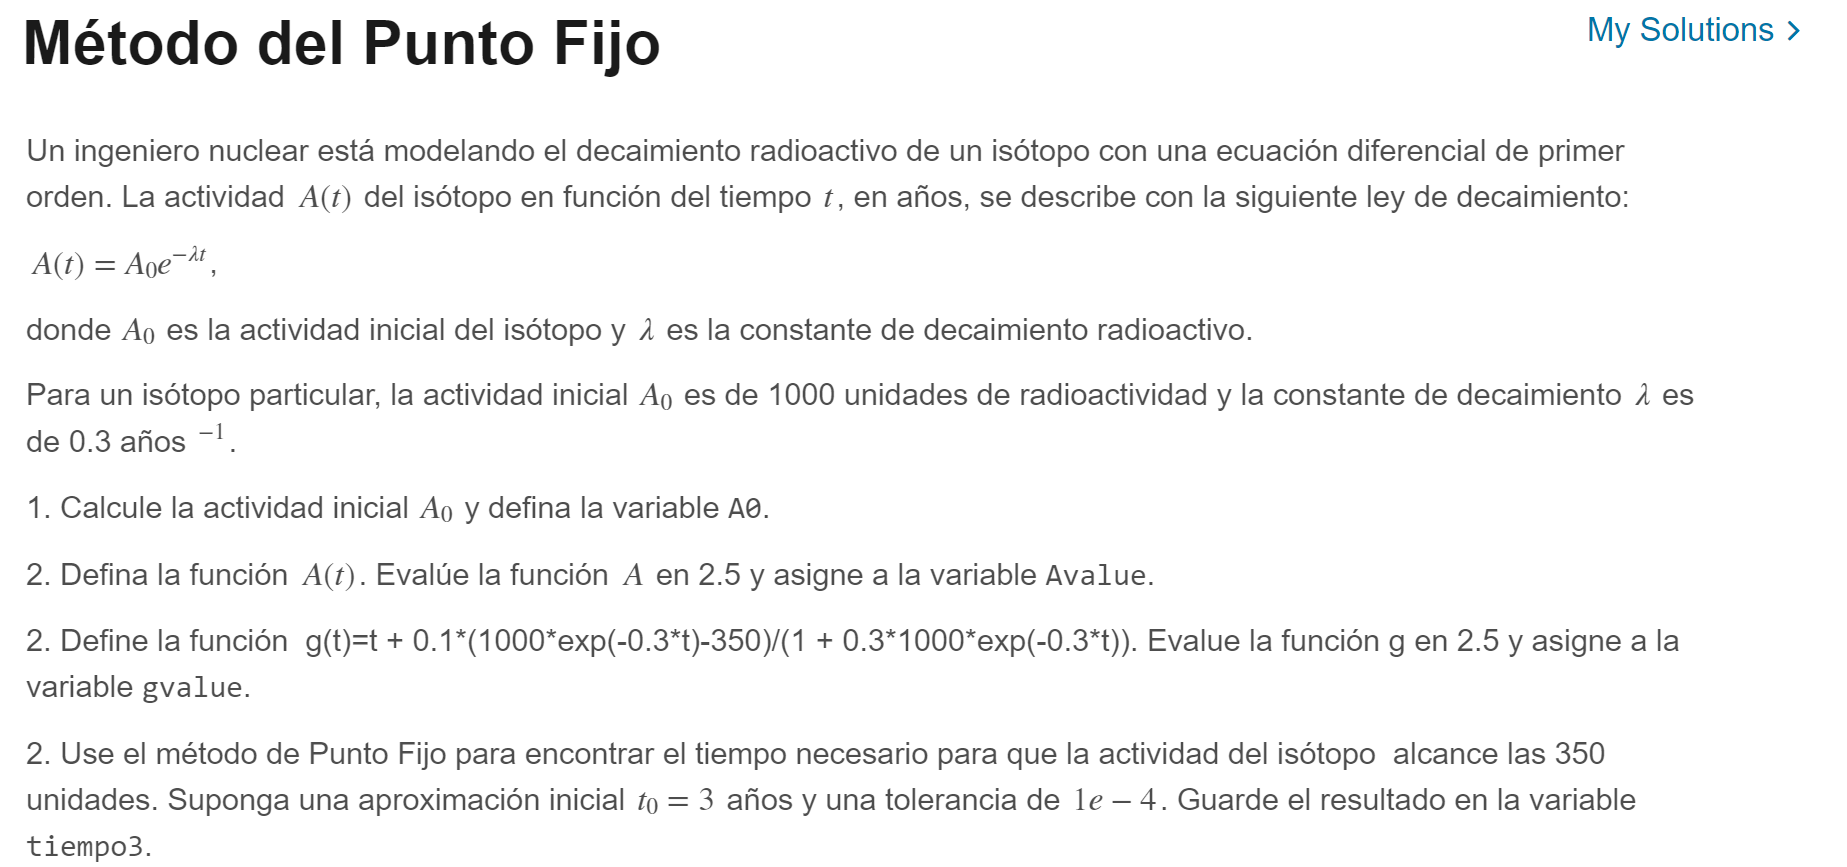

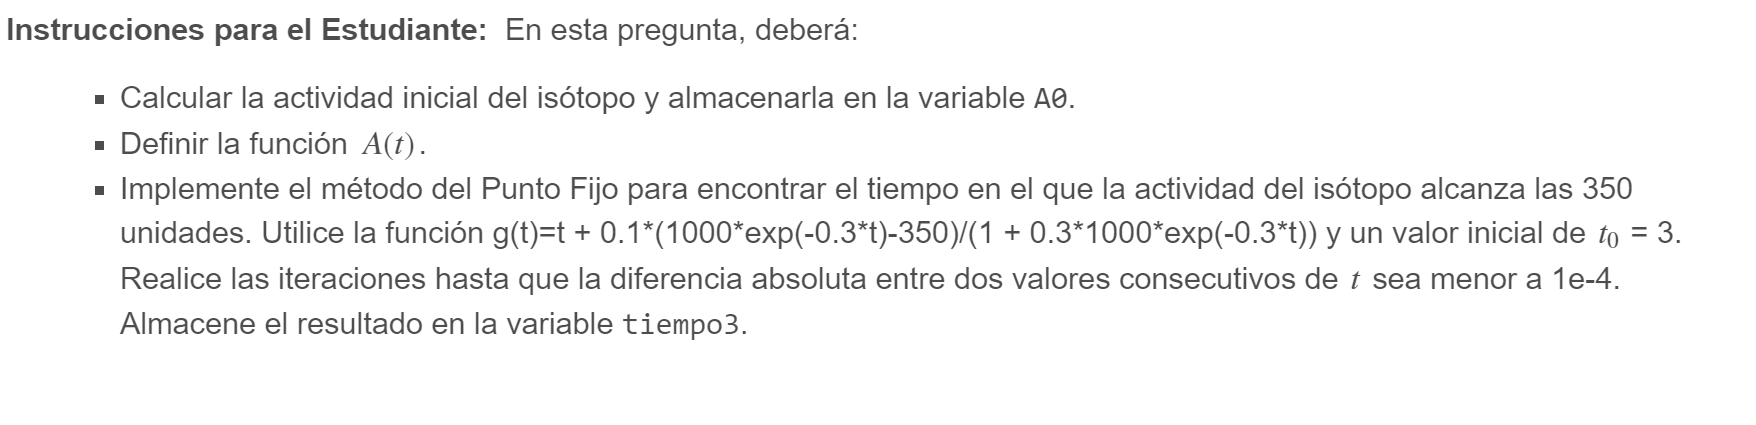

syms t
A0=1000;
lambda = 0.3; % constante de decaimiento
% La función de actividad
A = @(t) A0 * exp( -lambda*t);
Avalue=A(2.5);
%La función g
g=@(t) t + 0.1*(1000*exp(-0.3*t)-350)/(1 + 0.3*1000*exp(-0.3*t));
gvalue= g(2.5);
tiempo3 = punto_fijo(g,3, 1e-4) % calcular el tiempo con actividad de 350 unidades

tiempo3 = 3.4965

% Método del Punto Fijo para encontrar el tiempo con actividad de 350 unidades
function t_350 = punto_fijo(g,t0, tol)
 
error = 1;
x0 = t0;
while error > tol
    x0 = g(t0);
    error = abs(x0-t0)/abs(x0);
    t0 = x0;
 
end

t_350 = x0;

end